clear all

plotResPts = 100;

L1.A1 = zeros(14,1);
L1.A2 = zeros(14,1);

L2.A1 = zeros(14,1);
L2.A2 = zeros(14,1);

**Lens1**

% 1st Surface
L1.A1(4) = (-5.154e-6);
L1.A1(6) = (-2.450e-8);
L1.A1(8) = (-5.260e-11);
L1.A1(10) = (-6.692e-13);

L1.R1 = 27.321;
L1.aperture = 14.0; %CA - SemiDiameter
L1.K1 = 0;

%2nd Surface
L1.A2(4) = (-7.987e-6);
L1.A2(6) = (-1.561e-8);
L1.A2(8) = (-3.267e-10);
L1.A2(10) = (1.499e-13);

L1.R2 = 34.393;
% L1.D2 = 12.8*2;
L1.K2 = 0;

% General
L1.t = 3.5;
L1.n = 3.4;

**Lens2**

% 1st Surface
L2.A1(4) = (-3.273e-4);
L2.A1(6) = (-1.263e-6);
L2.A1(8) = (8.419e-9);
L2.A1(10) = (0.0);

L2.R1 = -2861.0;
L2.aperture = 8.0; %CA - SemiDiameter
L2.K1 = 0;

%2nd Surface
L2.A2(4) = (-3.194e-4);
L2.A2(6) = (4.309e-8);
L2.A2(8) = (8.151e-9);
L2.A2(10) = (0.0);

L2.R2 = 118.099;
% L2.D2 = 7.5*2;
L2.K2 = 0;

% General
L2.t = 2.5;
L2.n = 2.252;

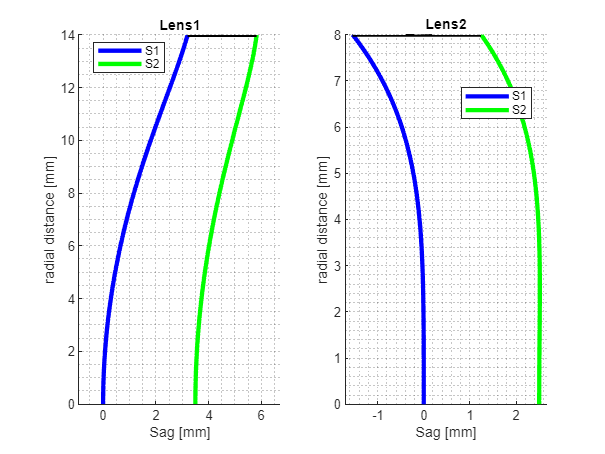

figure('Name', 'My Aspheric Surface')

subplot(121)

hold on, axis equal
ylabel('radial distance [mm]')
xlabel('Sag [mm]')

[L1.z1, L1.y1] = aspheric_surface_sag_eq(L1.aperture, L1.R1, L1.K1, L1.A1, plotResPts);
[L1.z2, L1.y2] = aspheric_surface_sag_eq(L1.aperture, L1.R2, L1.K2, L1.A1, plotResPts);

plot(L1.z1, L1.y1, 'b-', 'LineWidth', 3.0, 'DisplayName', 'S1');
plot(L1.z2+L1.t, L1.y2, 'g-', 'LineWidth', 3.0, 'DisplayName', 'S2');
pNotForLegend = plot([L1.z1(end);L1.z2(end)+L1.t], [L1.y1(end);L1.y2(end)], 'k-', 'LineWidth', 3.0,'DisplayName', '');
pNotForLegend.HandleVisibility  = 'off';
title('Lens1')
legend('show', 'Location','best')
grid minor

subplot(122)

hold on, axis equal
ylabel('radial distance [mm]')
xlabel('Sag [mm]')

[L2.z1, L2.y1] = aspheric_surface_sag_eq(L2.aperture, L2.R1, L2.K1, L2.A1, plotResPts);
[L2.z2, L2.y2] = aspheric_surface_sag_eq(L2.aperture, L2.R2, L2.K2, L2.A1, plotResPts);

plot(L2.z1, L2.y1, 'b-', 'LineWidth', 3.0, 'DisplayName', 'S1');
plot(L2.z2+L2.t, L2.y2, 'g-', 'LineWidth', 3.0, 'DisplayName', 'S2');
pNotForLegend = plot([L2.z1(end);L2.z2(end)+L2.t], [L2.y1(end);L2.y2(end)], 'k-', 'LineWidth', 3.0,'DisplayName', '');
pNotForLegend.HandleVisibility  = 'off';
title('Lens2')
legend('show', 'Location','best')
grid minor